# Source Statistics (Cluster Permutation Tests) in Fieldtrip

In this tutorial we will be statistically testing whether gamma power (40-70Hz) differs between the baseline period (1.2s long) and the visual grating period (1.2s long). We have a group of 14 subjects and we have already localised visual gamma power at the single-subject level using an LCMV beamformer (saved as `sourcepreS1.mat `and `sourcepstS1.mat`).

**NOTE:** Make sure all `.mat` source localisation variables have the same `.pos `field, corresponding to the template_grid defined in MNI space.

**Background:**

For more background on cluster-based permutation testing and interpreting results, please read the following articles:

*Maris, E., & Oostenveld, R. (2007). Nonparametric statistical testing of EEG-and MEG-data. Journal of neuroscience methods, 164(1), 177-190. *[https://doi.org/10.1016/j.jneumeth.2007.03.024](https://doi.org/10.1016/j.jneumeth.2007.03.024)

*Sassenhagen, J., & Draschkow, D. (2019). Cluster‐based permutation tests of MEG/EEG data do not establish significance of effect latency or location. Psychophysiology, 56(6), e13335. *[https://doi.org/10.1111/psyp.13335](https://doi.org/10.1111/psyp.13335)

## Set up Paths

% Path to the Fieldtrip Toolbox
path_to_fieldtrip       = '/Users/rseymoue/Documents/GitHub/fieldtrip/';
 
% Path to MQ_MEG_Scripts
path_to_MQ_MEG_Scripts  = '/Users/rseymoue/Documents/GitHub/MQ_MEG_Scripts/';

% Add Fieldtrip
addpath(path_to_fieldtrip);
ft_defaults;

% Add MQ_MEG_Scripts
addpath(genpath(path_to_MQ_MEG_Scripts));

## Specify Data Save Path and Subject IDs

save_path               = '/Volumes/Robert T5/ME176_data_preprocessed/';

subject                 = {'3565','3566','3588','3589','3610','3611',...
                        '3627','3630','3633','3655','3658','3659',...
                        '3675','3676'};

## Load the source data into two cell arrays

The first thing we need to do is load the data into two arrays, one for the baseline power and one for the grating power. We end up with a 1x14 cell array `source_pre_all `and 1x14 cell array `source_post_all`.

source_pre_all          = [];
source_post_all         = [];

for sub = 1:length(subject)
    fprintf('Loading for for subject %s\n', subject{sub});
    cd([save_path subject{sub}]);
    
    % Load baseline data
    load('sourcepreS1.mat');
    % Load grating data
    load('sourcepstS1.mat');
    
    % Put these into the two arrays outside the loop
    source_pre_all{sub}     = sourcepreS1;
    source_post_all{sub}    = sourcepstS1;
    
    clear sourcepreS1 sourcepstS1
end

## `ft_sourcestatistics`

**NOTE: **Here we are performing one-sided testing for demonstration... however you will probably want to perform two-sided testing for your data. Therefore please change to: `cfg.tail = 0`

**NOTE: **Here we are performing a dependent-samples t-test. If you wish to test an independent experimental design, please change to `cfg.statistic = 'ft_statfun_depsamplesT'`

%% Perform Statistical Analysis
cfg                     = [];
cfg.dim                 = source_post_all{1}.dim;
cfg.method              = 'montecarlo';
cfg.statistic           = 'ft_statfun_depsamplesT';
cfg.parameter           = 'pow';
cfg.correctm            = 'cluster';
cfg.computecritval      = 'yes';
cfg.numrandomization    = 4000;
cfg.tail                = 1;    % One sided testing

% Design Matrix
nsubj                   = numel(source_post_all);
cfg.design(1,:)         = [1:nsubj 1:nsubj];
cfg.design(2,:)         = [ones(1,nsubj) ones(1,nsubj)*2];
% row of design matrix that contains unit variable (in this case: subjects)
cfg.uvar                = 1;
% row of design matrix that contains independent variable (the conditions)
cfg.ivar                = 2; 

% Perform statistical analysis
[stat]                  = ft_sourcestatistics(cfg,source_post_all{:},...
                        source_pre_all{:});


% Show raw source level statistics (2D plot)
cfg                     = [];
cfg.method              = 'ortho';
cfg.funparameter        = 'stat';
cfg.location            = 'max';
%cfg.maskparameter      = 'mask'; %turn on to show mask
ft_sourceplot(cfg,stat);
ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
colormap(flipud(brewermap(64,'RdBu'))) % change the colormap


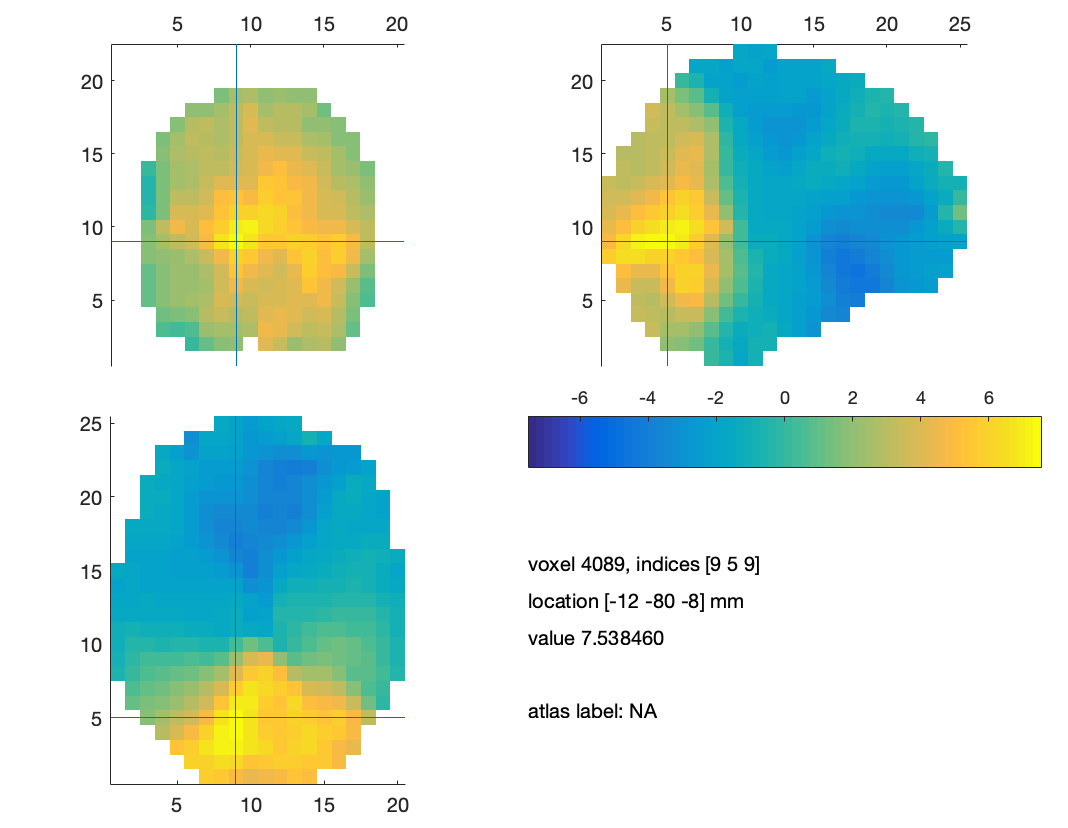

## Interpolate and Plot

%% Interpolate onto SPM T1 Brain
mri                 = ft_read_mri([path_to_fieldtrip ...
                    'template/anatomy/single_subj_T1.nii']);

cfg                 = [];
cfg.voxelcoord      = 'no';
cfg.parameter       = 'stat';
cfg.interpmethod    = 'nearest';
statint             = ft_sourceinterpolate(cfg, stat, mri);
cfg.parameter       = 'mask';
maskint             = ft_sourceinterpolate(cfg, stat,mri);
statint.mask        = maskint.mask;

**2D Plot:**

cfg                 = [];
cfg.zlim            = 'maxabs';
cfg.funparameter    = 'stat';
cfg.maskparameter   = 'mask';
cfg.location        = 'max';
ft_sourceplot(cfg,statint);
ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
colormap(flipud(brewermap(64,'RdBu'))) % change the colormap
print('source_int_2D','-dpng','-r300');

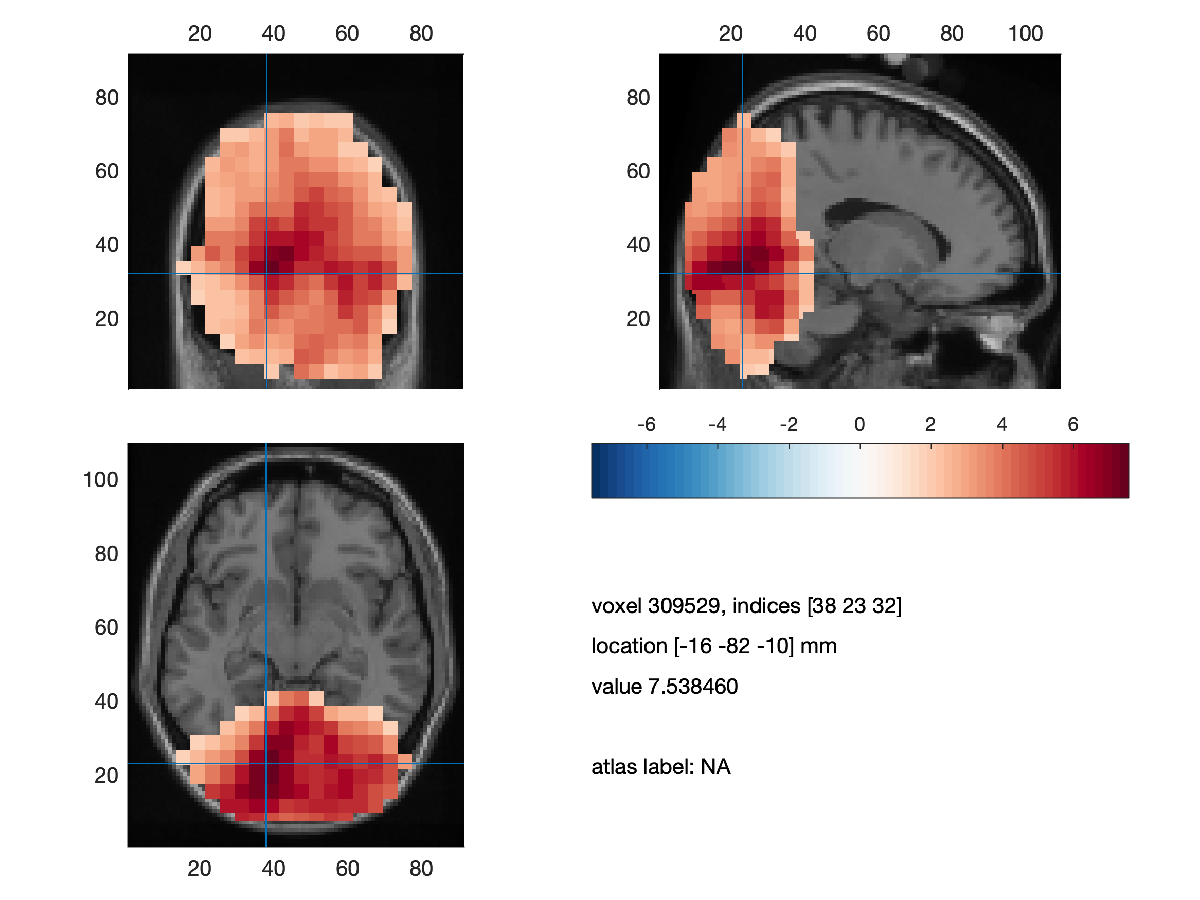

**3D Plot:**

cfg                = [];
cfg.method         = 'surface';
cfg.maskparameter  = 'mask';
cfg.funparameter   = 'stat';
cfg.projmethod     = 'nearest';
cfg.surfinflated   = 'surface_inflated_both.mat';
cfg.camlight       = 'no';
ft_sourceplot(cfg, statint);
ft_hastoolbox('brewermap', 1);         % ensure this toolbox is on the path
colormap(flipud(brewermap(64,'RdBu'))) % change the colormap
light ('Position',[0 0 50])
light ('Position',[0 -50 0])
material dull;
drawnow;
view([0 0]);
set(gca,'FontSize',14);
print('source_int_3D','-dpng','-r300');

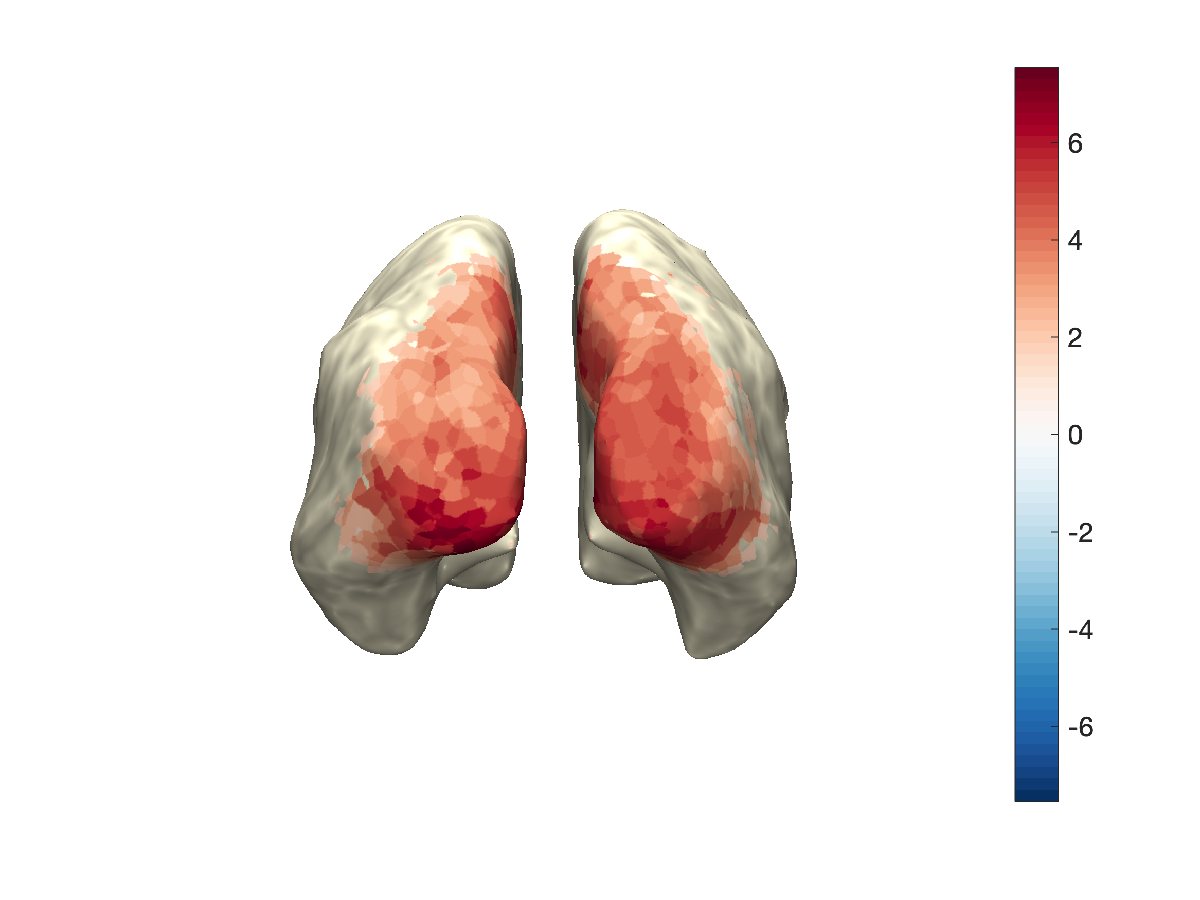

## Export to Nifti Format

%% Export to nifti
% Run this if you want to export the clusters rather than the raw stats
statint.stat(isnan(statint.stat)) = 0;
statint.stat                      = (statint.stat(:).*statint.mask(:));

% Use ft_sourcewrite to export to nifti
cfg                         = [];
cfg.filetype                = 'nifti';
cfg.filename                = 'group_gamma_clustered';
cfg.parameter               = 'stat';
ft_sourcewrite(cfg,statint);